export_dir = 'examples/phase_study/results/pulse_plots_2/';

Unrecognized function or variable 't_prime'.

[~,~,~] = mkdir(export_dir);


a = 10;
b = 3;
c = 15;
t_prime = t_c_subsampled(160) - t_r;
disp(min(t_prime(:)));
disp(max(t_prime(:)));
t_prime_plo = t_prime(a,b,c,:);
t_prime_plo = t_prime_plo(:);

t_prime_min =  t_c_subsampled(1) - t_r;
t_prime_max = t_c_subsampled(160) - t_r;
t_min = min(t_prime_min(:));
t_max = max(t_prime_max(:));


% Symmetric
t_plo = linspace(t_min, t_max, 100);

laser_t = exp(-(t_plo-t0).^2./laser_pulse_time_sigma.^2);
laser_t_plo = laser_t(:);


close all;
plot(t_plo * 1e12,laser_t_plo,'LineWidth',2);
set(gca,'FontName','Helvetica','FontSize',12);
xlabel('Time (ps)');
ylabel('Intensity (E_0^2 = 1)');
ylim([-0.1,1.1]);
xlim([-1 1.5]);
set(gcf,'Position',[50,50,400,400]);
exportgraphics(gca,strcat(export_dir,'symmetric.png'),'Resolution',400);


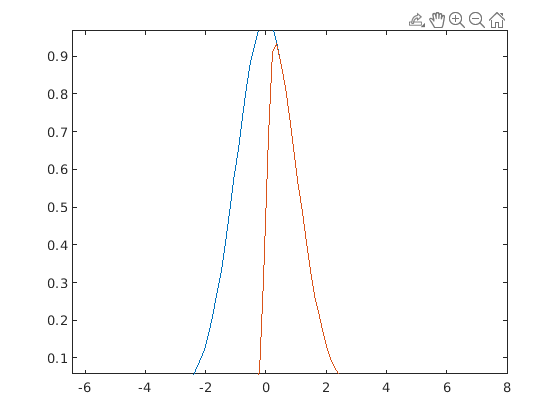

% ASymmetric1
laser_t = exp(-(t_plo-t0).^2./laser_pulse_time_sigma.^2);
alpha = 1e14;
skew = 0.5*(1+erf(-alpha * ((-t_plo+t0))));
laser_t =  laser_t.*  skew;
laser_t_plo = laser_t(:);

close all;

plot(t_plo * 1e12,laser_t_plo,'LineWidth',2);
set(gca,'FontName','Helvetica','FontSize',12);
xlabel('Time (ps)');
ylabel('Intensity (E_0^2 = 1)');
ylim([-0.1,1.1]);xlim([-1 1.5]);set(gcf,'Position',[50,50,400,400]);
exportgraphics(gca,strcat(export_dir,'asymmetric_1.png'),'Resolution',400);

% ASymmetric1
laser_t = exp(-(t_plo-t0).^2./laser_pulse_time_sigma.^2);
alpha = -1e14;
skew = 0.5*(1+erf(-alpha * ((-t_plo+t0))));
laser_t =  laser_t.*  skew;
laser_t_plo = laser_t(:);

close all;
plot(t_plo * 1e12,laser_t_plo,'LineWidth',2);
set(gca,'FontName','Helvetica','FontSize',12);
xlabel('Time (ps)');
ylabel('Intensity (E_0^2 = 1)');
ylim([-0.1,1.1]);xlim([-1 1.5]);set(gcf,'Position',[50,50,400,400]);
exportgraphics(gca,strcat(export_dir,'asymmetric_2.png'),'Resolution',400);


%Double pulse

laser_t = exp(-(t_plo-t0).^2./laser_pulse_time_sigma.^2);
alpha = 1e14;
skew = 0.5*(1+erf(-alpha * ((-t_plo+t0))));
skew = 1;
laser_t =  laser_t.*  skew;

t0_2 = 0.1e-12;
laser_t2 = exp(-(t_plo-t0_2).^2./(laser_pulse_time_sigma/2).^2);
alpha2 = -1e14;
skew2 = 0.5*(1+erf(-alpha2 * ((-t_plo+t0_2))));
skew2 = 1;
laser_t2 =  laser_t2.*  skew2;

t0_3 = 0.9e-12;
laser_t3 = exp(-(t_plo-t0_3).^2./(laser_pulse_time_sigma/2).^2);
alpha2 = -1e14;
skew3 = 0.5*(1+erf(-alpha2 * ((-t_plo+t0_3))));
skew3 = 1;
laser_t3 =  laser_t3.*  skew3;


laser_t =  0.2 * laser_t2 + 1 * laser_t + 0.2 * laser_t3;


laser_t_plo = laser_t(:);

close all;
plot(t_plo * 1e12,laser_t_plo,'LineWidth',2);
set(gca,'FontName','Helvetica','FontSize',12);
xlabel('Time (ps)');
ylabel('Intensity (E_0^2 = 1)');
ylim([-0.1,1.1]);xlim([-1 1.5]);set(gcf,'Position',[50,50,400,400]);
exportgraphics(gca,strcat(export_dir,'double_pulse.png'),'Resolution',400);


%Double pulse 1

laser_t = exp(-(t_plo-t0).^2./laser_pulse_time_sigma.^2);
alpha = 1e14;
skew = 0.5*(1+erf(-alpha * ((-t_plo+t0))));
skew = 1;
laser_t =  laser_t.*  skew;

t0_2 = 0.1e-12;
laser_t2 = exp(-(t_plo-t0_2).^2./(laser_pulse_time_sigma/2).^2);
alpha2 = -1e14;
skew2 = 0.5*(1+erf(-alpha2 * ((-t_plo+t0_2))));
skew2 = 1;
laser_t2 =  laser_t2.*  skew2;

t0_3 = 0.9e-12;
laser_t3 = exp(-(t_plo-t0_3).^2./(laser_pulse_time_sigma/2).^2);
alpha2 = -1e14;
skew3 = 0.5*(1+erf(-alpha2 * ((-t_plo+t0_3))));
skew3 = 1;
laser_t3 =  laser_t3.*  skew3;


% laser_t =  0.2 * laser_t2 + 1 * laser_t + 0.2 * laser_t3;
laser_ta =  0.2 * laser_t2 + 1 * laser_t ;
laser_tb =  1 * laser_t + 0.2 * laser_t3;
laser_tn =  -0.2 * laser_t2 + 1 * laser_t - 0.2 * laser_t3;

laser_t1_plo = laser_ta(:);
laser_t2_plo = laser_tb(:);
laser_tn_plo = laser_tn(:);

close all;
plot(t_plo * 1e12,laser_t1_plo,'LineWidth',2);
set(gca,'FontName','Helvetica','FontSize',12);
xlabel('Time (ps)');
ylabel('Intensity (E_0^2 = 1)');
ylim([-0.1,1.1]);xlim([-1 1.5]);set(gcf,'Position',[50,50,400,400]);
exportgraphics(gca,strcat(export_dir,'double_pulse_1.png'),'Resolution',400);

close all;
plot(t_plo * 1e12,laser_t2_plo,'LineWidth',2);
set(gca,'FontName','Helvetica','FontSize',12);
xlabel('Time (ps)');
ylabel('Intensity (E_0^2 = 1)');
ylim([-0.1,1.1]);xlim([-1 1.5]);set(gcf,'Position',[50,50,400,400]);
exportgraphics(gca,strcat(export_dir,'double_pulse_2.png'),'Resolution',400);

close all;
plot(t_plo * 1e12,laser_tn_plo,'LineWidth',2);
set(gca,'FontName','Helvetica','FontSize',12);
xlabel('Time (ps)');
ylabel('Intensity (E_0^2 = 1)');
ylim([-0.1,1.1]);xlim([-1 1.5]);set(gcf,'Position',[50,50,400,400]);
exportgraphics(gca,strcat(export_dir,'double_pulse_n.png'),'Resolution',400);



laser_t = exp(-(t_plo-t0).^2./laser_pulse_time_sigma.^2);
alpha = 1e14;
skew = 0.5*(1+erf(-alpha * ((-t_plo+t0))));
laser_t =  laser_t.*  skew;

t0_2 = 0.3e-12;
laser_t2 = exp(-(t_plo-t0_2).^2./(laser_pulse_time_sigma/2).^2);
alpha2 = -1e14;
skew2 = 0.5*(1+erf(-alpha2 * ((-t_plo+t0_2))));
laser_t2 =  laser_t2.*  skew2;


laser_t =  0.2 * laser_t2 + laser_t;

% b_asym = 0.999999;
% asymmetry_pulse = 1./(1 + b_asym*(t_plo-t0)./sqrt((t_plo-t0).^2 + laser_pulse_time_sigma.^2));
% laser_t = laser_t .^ asymmetry_pulse;



plot(t_plo,laser_t_plo, t_plo,skew);
% ylim([0,1]);

laser_t = exp(-(t_prime-t0).^2./laser_pulse_time_sigma.^2);
b_asym = 0.999;
asymmetry_pulse = 1./(1 + b_asym*(t_prime-t0)./sqrt((t_prime-t0).^2 + laser_pulse_time_fwhm.^2));
laser_t = laser_t .^ asymmetry_pulse;

% 
% tau1 = 0.2e-12; tau2 = 1e-12;
% %
% %                 laser_t = (-exp(-(t_prime-t0)./tau1) + exp(-(t_prime-t0)./tau2))./((tau2/tau1).^(tau1/(tau1 - tau2)) ...
% %                     - (tau2/tau1).^(tau2/(tau1 - tau2)));
% laser_t = (-exp(-(t_prime-t0)./tau1) + exp(-(t_prime-t0)./tau2))./((tau2/tau1).^(tau1/(tau1 - tau2)) ...
%     - (tau2/tau1).^(tau2/(tau1 - tau2)));
% 
% 
% laser_t(t_prime<0) = 0;



laser_t_plo = laser_t(a,b,c,:);
laser_t_plo = laser_t_plo(:);
plot(t_prime_plo,laser_t_plo);
ylim([0,1]);

x = linspace(-7,7,100);
gaussian = @(x) exp(-x.^2/2);
% skewedgaussian = @(x,alpha) gaussian(x).*normcdf(alpha*x)*sqrt(2*pi);
skewedgaussian = @(x,alpha) 0.5*gaussian(x).*erfc(-alpha*x);
plot(x, gaussian(x),x, ...
    ...
    skewedgaussian(x,5));
laser_t = exp(-(t_plo-t0).^2./laser_pulse_time_sigma.^2);
alpha = 1e14;
skew = 0.5*(1+erf(-alpha * ((-t_plo+t0))));
laser_t =  laser_t.*  skew;


t0_2 = 0.3e-12;
laser_t2 = exp(-(t_plo-t0_2).^2./(laser_pulse_time_sigma).^2);
alpha2 = -1e14;
skew2 = 0.5*(1+erf(-alpha2 * ((-t_plo+t0_2))));
laser_t2 =  laser_t2.*  skew2;


laser_t =  0 * laser_t2 + laser_t;

dt = t_plo(2) - t_plo(1);
L = length(t_plo);
Fs = 1/dt;
f = Fs*(-(L/2):(L/2)-1)/L;

fft_laser_t = fftshift(fft(fftshift(laser_t)));
alpha_f = -0.2e-12;
skew_f = 0.5*(1+erf(-alpha_f * ((f))));
fft_laser_t = skew_f .*fft_laser_t;
close all;


% plot(f,skew_f,f,abs(fft_laser_t));
laser_t_plo = laser_t(:);
plot(t_plo, laser_t_plo, t_plo,abs(fftshift(ifft(fft_laser_t))));


t_plo = linspace(t_min, t_max, 50);
laser_t = sinc(-(t_plo-t0)./(pi * laser_pulse_time_sigma / 2)).^2;
alpha_skew = 1e12;
skew = 0.5*(1+erf(-alpha_skew * ((-t_plo+t0))));
laser_t =  laser_t.*  skew;

laser_t_plo = laser_t(:);
close all;
plot(t_plo, laser_t_plo);